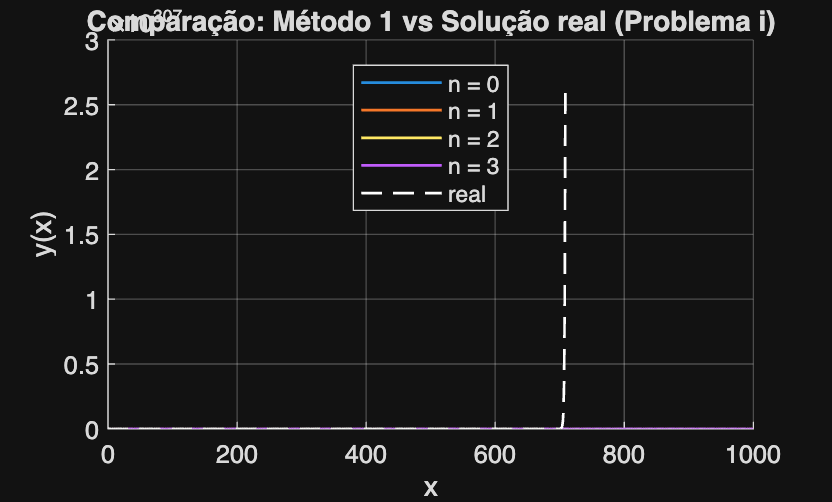

%a
%i
format long
q = @(x) -1 + 0*x; 
r = @(x) x;

%solução exata do enunciado
yr = @(x) (exp(1+x) + x - x*exp(2) - exp(1-x)) / (exp(2) - 1);

x = linspace(0,1000, 1000);

figure;
hold on;

for n = 0:3
    u= metodo1(n, q, r);
    ulista = arrayfun(u,x);
    
    %plot das aproximações
    plot(x, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

%plot da solução exata
plot(x, yr(x), 'w--', 'LineWidth', 1, 'DisplayName', 'real');

xlabel('x');
ylabel('y(x)');
title('Comparação: Método 1 vs Solução real (Problema i)');
legend('Location', 'best');
grid on;
hold off;


errosia= zeros(1,4);
for n=0:3
    u=metodo1(n,q,r);
    t= @(x) (yr(x) - u(x)).^2;
    errosia(:,n+1)= sqrt(integral(t,0,1));

end
errosia

errosia =    0.005612285919159   0.000148546950626   0.000015443132993   0.000000291820570


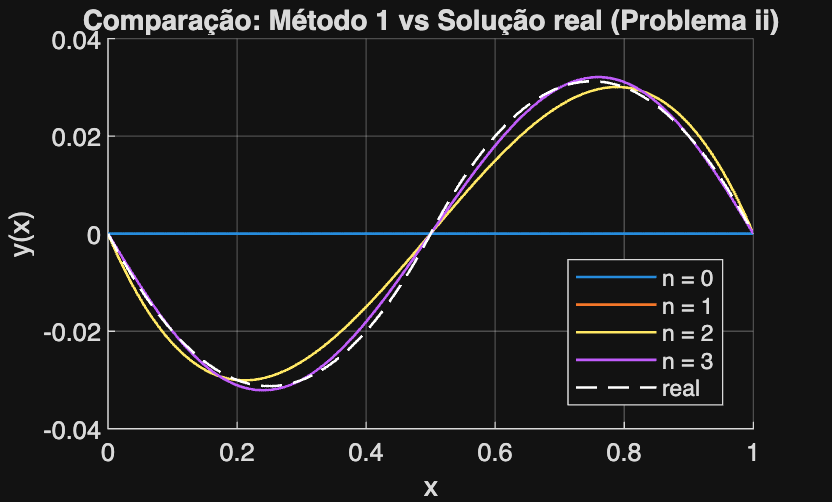

%a
%ii
format long
q = @(x) 0 * x;
r = @(x) (x >= 0 & x <= 0.5) * 1 + (x > 0.5 & x <= 1) * (-1);

%solução exata do problema ii
yr = @(x) (x >= 0 & x <= 0.5) .* (0.5 * x.^2 - 0.25 * x) + (x > 0.5 & x <= 1) .* (-0.5 * (x - 1).^2 - 0.25 * (x - 1));


x = linspace(0,1, 1000);
figure;
hold on;

for n = 0:3
    u= metodo1(n, q, r);
    ulista = arrayfun(u,x);
    
    %plot das aproximações
    plot(x, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

%plot da solução exata
plot(x, yr(x), 'w--', 'LineWidth', 1, 'DisplayName', 'real');

xlabel('x');
ylabel('y(x)');
title('Comparação: Método 1 vs Solução real (Problema ii)');
legend('Location', 'best');
grid on;
hold off;


errosiia= zeros(1,4);
for n=0:3
    u=metodo1(n,q,r);
    t= @(x) (yr(x) - u(x)).^2;    
    errosiia(:,n+1)= sqrt(integral(t,0,1));

end
errosiia

errosiia =    0.022821773229382   0.003049687727964   0.003049687727964   0.001053437285099   0.001053437285099   0.000504294706537   0.000504294706537


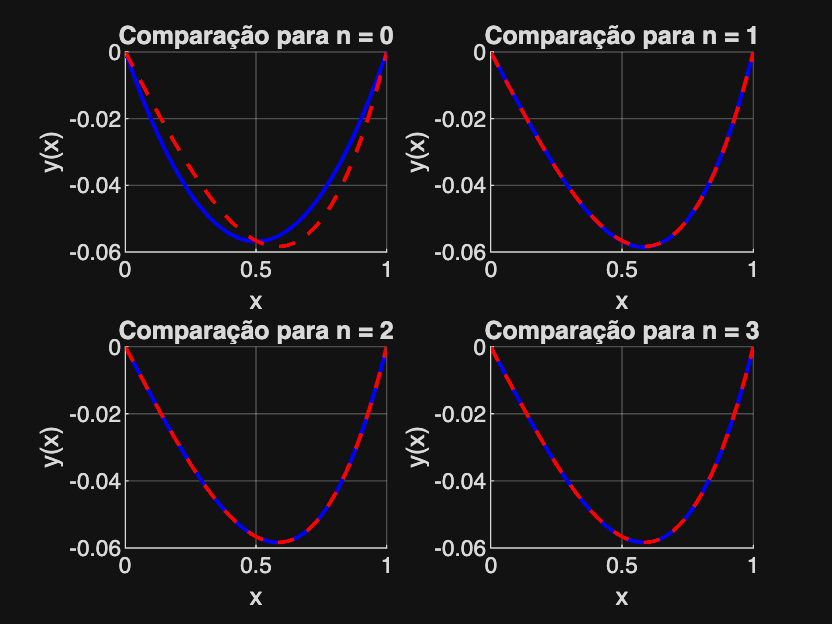

%a
%criar 4 graficos (um para cada n vs solução exata)
%i
format long
q = @(x) -1 + 0*x; 
r = @(x) x;

%solução exata do enunciado
yr = @(x) (exp(1+x) + x - x*exp(2) - exp(1-x)) / (exp(2) - 1);

x = linspace(0, 1, 1000); 

figure('Name', 'Método 1 vs Solução Real (Problema i)', 'Position', [100, 100, 800, 600]);

for n = 0:3
    subplot(2, 2, n+1); 
    hold on;
    
    u = metodo1(n, q, r);
    ulista = arrayfun(u, x);
    
    plot(x, ulista, 'b-', 'LineWidth', 1.5);
    plot(x, yr(x), 'r--', 'LineWidth', 1.5);
    xlabel('x');
    ylabel('y(x)');
    title(['Comparação para n = ' num2str(n)]);
    grid on;
    hold off;
end

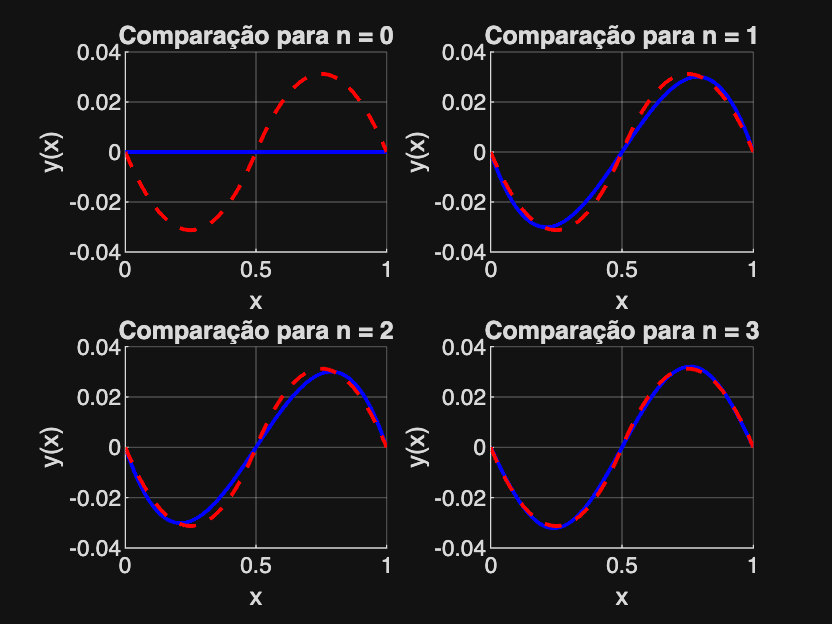

%a
%criar 4 graficos (um para cada n vs solução exata)
%ii
format long
q = @(x) 0 * x;
r = @(x) (x >= 0 & x <= 0.5) * 1 + (x > 0.5 & x <= 1) * (-1);

%solução exata do problema ii
yr = @(x) (x >= 0 & x <= 0.5) .* (0.5 * x.^2 - 0.25 * x) + (x > 0.5 & x <= 1) .* (-0.5 * (x - 1).^2 - 0.25 * (x - 1));

x = linspace(0, 1, 1000); 

figure('Name', 'Método 1 vs Solução Real (Problema i)', 'Position', [100, 100, 800, 600]);

for n = 0:3
    subplot(2, 2, n+1); 
    hold on;
    
    u = metodo1(n, q, r);
    ulista = arrayfun(u, x);
    
    plot(x, ulista, 'b-', 'LineWidth', 1.5);
    
    plot(x, yr(x), 'r--', 'LineWidth', 1.5);
    
    xlabel('x');
    ylabel('y(x)');
    title(['Comparação para n = ' num2str(n)]);
    grid on;
    hold off;
end